clear
dir

.                       costFunction.m          ex2_companion.mlx       ex2data2.txt            plotData.m              sigmoid.m               token.mat               
..                      costFunctionReg.m       ex2_nj.mlx              lib                     plotDecisionBoundary.m  sigmoidd.m              
.MATLABDriveTag         ex2.mlx                 ex2data1.txt            mapFeature.m            predict.m               submit.m                



data = load('ex2data1.txt');
X = data(:, 1:2);
y = data(:, 3);
[m, n] = size(X);

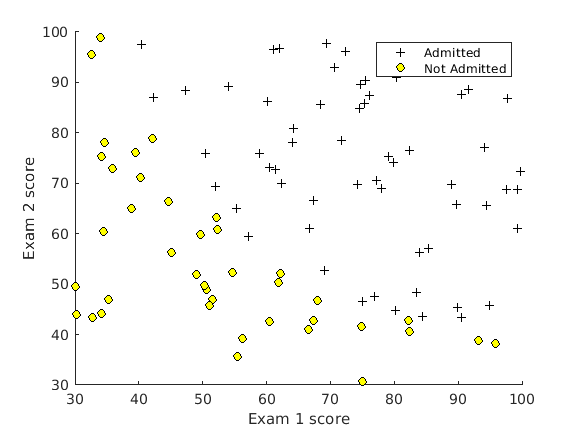

% Visualizing the data, if possible, helps in understanding the nature of
% our hypothesis
plotData(X,y);

% Adding the intercept term x0
X = [ones(m,1) X];
initial_theta = zeros(n + 1, 1);

[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at inital theta %f\n', cost);

Cost at inital theta 0.693147


disp('Gradient at initial theta:');

Gradient at initial theta:


disp(grad);

   -0.1000
  -12.0092
  -11.2628



% minimizing theta
options = optimoptions(@fminunc, 'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


disp('Minm theta:');

Minm theta:


disp(theta);

  -25.1613
    0.2062
    0.2015



fprintf('Cost at minimum theta = %f\n', cost);

Cost at minimum theta = 0.203498


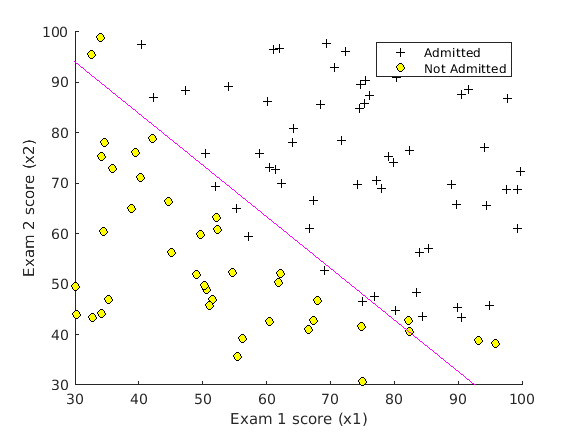

% Plot decision boundary
hold on;
x_vals = [min(X(:, 2)) - 2, max(X(:, 2)) + 2];
y_vals = -1/theta(3) * (theta(2) * x_vals + theta(1));
plot(x_vals, y_vals, '-m');
legend('Admitted', 'Not admitted', 'Decision Boundary');
axis([30, 100, 30, 100]);
hold off;

hold on;
xlabel('Exam 1 score (x1)')
ylabel('Exam 2 score (x2)')
legend('Admitted', 'Not Admitted');
hold off;

prob = sigmoid([1 45 85] * theta);
fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291



p = predict(theta, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

Training Accuracy: 89.000000


A = [p y]

A =      0     0
     0     0
     0     0
     1     1
     1     1
     0     0
     1     1
     0     1
     1     1
     1     1
